## Benjamin Rosenberg    EECE 5644    Take Home Exam 4

# Question 1

For this question, a multilayer perceptron (MLP) was used to estimate the second value, $x_2$, in a dataset of two-dimensional samples $\mathbf{x} = [x_1\ x_2]^T$. The MLP was trained to minimize mean-squared error, which achieves maximum-likelihood estimation of the MLP parameters for a given dataset.

This can be seen by derivation from maximum likelihood parameter estimation, given dataset $D=\{(x_1,y_1),...,(x_N,y_N)\}$ and parameter vector $\theta$:

$\hat{\theta}_{ML}=
\underset{\mathbf{\theta}}{argmax}\ p(D|\theta)$, which can be show to equal $\hat{\theta}_{ML}=
\underset{\mathbf{\theta}}{argmax}\sum_{n=1}^Nln(p(y_n|x_n,\theta)$. If we approximate $y$ as $y \approx h(x,\theta)+v$, where $p(v) \sim \mathcal{N}(0,\Sigma_v)$ then $p(y_n|x_n,\theta) \sim \mathcal{N}(h(x_n,\theta),\Sigma_v)$. By substituting in the Gaussian pdf and simplifying, we get 

$\hat{\theta}_{ML}=
\underset{\mathbf{\theta}}{argmin}\frac1N\sum_{n=1}^N\|y_n-h(x_n,\theta)\|_{2}^^^{2}$, which represent average mean-square error for the dataset with the model $h(x,\theta)$. Details of the derivation can be found in the section "Approximating a function that maps x to y using Max Likelihood..."  in the lecture 14 course notes provided by Prof. Erdogmuz.

### MLP Structure

The MLP consisted of a hidden layer, a softplus activation function between, then an output layer. The weights and biases of the MLP are vectorized for training as $\theta = \{b,A,d,C\}$, where $b$ is the input layer bias, $A$ is a matrix of the input layer weights, $d$ is the hidden layer bias, and $C$is a matrix of the hidden layer weights. The MATLAB function 'feedforwardnet' was used to implement the MLP as described. A custom softplus activation function, or transfer function as it is called in MATLAB, was created for 'feedforwardnnet' (see softplus.m and the folder '+softplus'). A MATLAB output of the MLP with 11 perceptrons is shown below, where the block labeled 'F' inside the hidden layer represents the softplus nonlinearity:

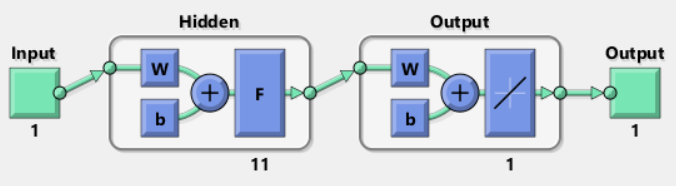

### MLP Initialization for Model Order Selection

Various MLP initializations were attempted, including initializing all biases and weights to zeros, initializing all biases and weights to uniform random values, and applying the Xavier initialization process as done in Exam 3. When using the Xavier initialization, the same MLP performance was achieved with a lower number of perceptrons and faster convergence times, compared with all biases and weights initialized to zeros or uniform values.

### Model Order Selection

10-fold cross-validation over 6 epochs was used to determine model order selection. In this case, model order selection was the optimal number of perceptrons at the hidden layer from the set {1,...,12}. All samples were generated using the provided exam4q1_generateData.m, with training sets $D_{train}$ of 1000 samples and $D_{test}$ of 10,000 samples. The MLP was trained using backpropogation on data from all of the designated training folds, and tested using the validation fold. A new fold was then selected for validation, with the remainder of folds used to train the MLP, and this process was repeated until all folds were used for validation. An estimated mean-squared error $MSE = \frac1N\sum_{i=1}^N (y_i - x_{2i})^2$ for each validation fold was calculated for all cross-validation combinations, where $N = \text{length(validation fold)}$, $y_i$ was the MLP output for a given sample $x_{1i}$ of the validation fold (which has an actual output $x_{2i}$). At the end of a cross-validation cycle for a given number of perceptrons, a mean MSE was calculated and stored in a matrix for later selection. The final trained weights and biases of the MLP with minimum MSE for a given perceptron count was also saved. This entire cross-validation procedure was repeated for 6 epochs, then the number of perceptrons corresponding to the minimum entry in the mean MSE matrix  was selected as the model order. From the selected model order, the trained weights and biases associated with the minimum MSE MLP instance were also returned. The file mlp_model_order_selection.m includes code implementing the model order selection process.

### Initialization and Training for Final Model

For each epoch of cross-validation, trained weights and biases from best-performing MLPs for each model order were saved. When the final model order was selected, the associated best-performing trained weights and biases were used to initialize the final MLP model. This initialization approach was used to minimize the chance of the final MLP converging to a local minima. The final MLP model was then trained on the entire training datset.

### Results

The plots below include data samples produced by exam4q1_generateData.m, and bar graphs of mean-squared error for each epoch of 10-fold cross-validation for the training dataset. Output of the selected model order is printed after the bar graphs, along with the mean-squared error (MSE) of the final trained MLP model evaluated on the 10,000 sample testing dataset. Across several iterations, the optimal model parameters were observed to be between 6-9 perceptrons, and MSE of the final trained MLP approximately 1.30 - 1.40.

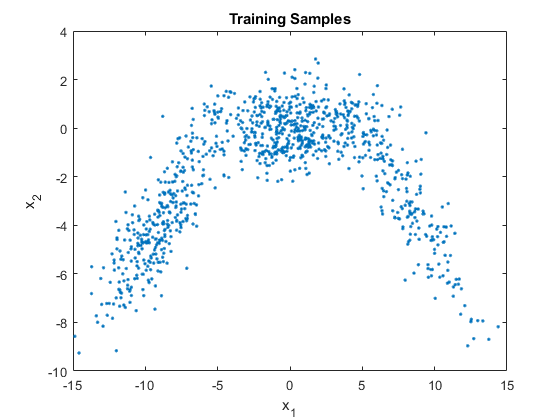

d_train = exam4q1_generateData(1000);
plot_samples(d_train,'Training Samples');

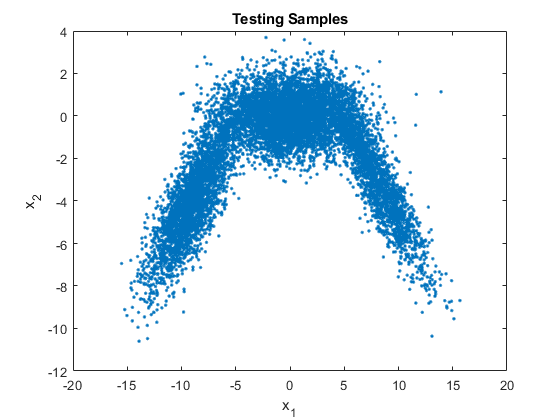

x1_train = d_train(1,:);
x2_train = d_train(2,:);
d_test = exam4q1_generateData(10000);
x1_test = d_test(1,:);
x2_test = d_test(2,:);
plot_samples(d_test,'Testing Samples');

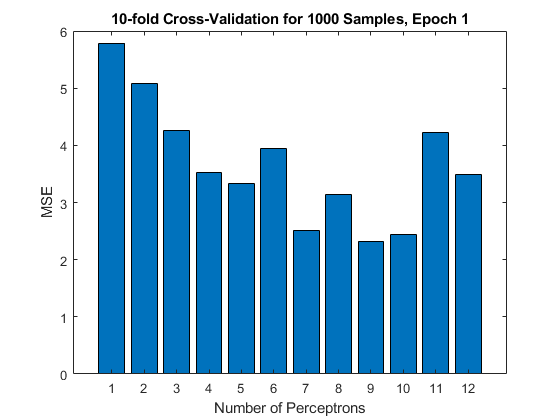

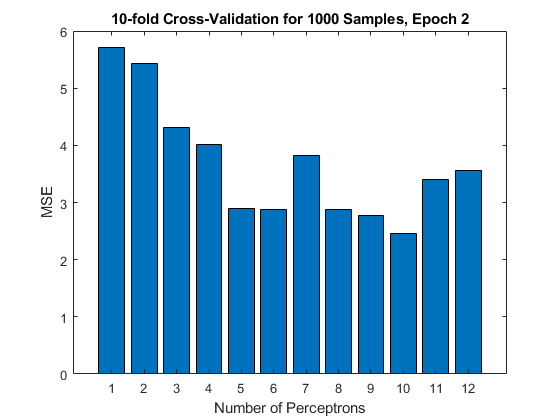

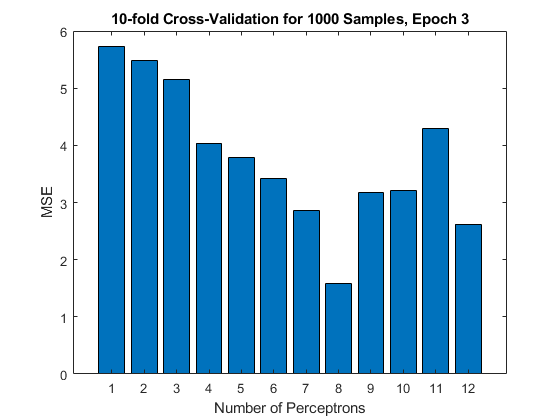

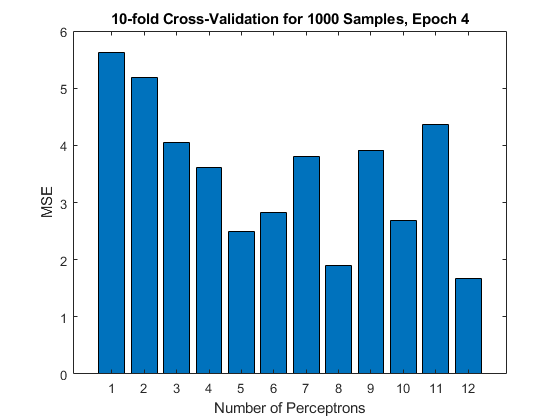

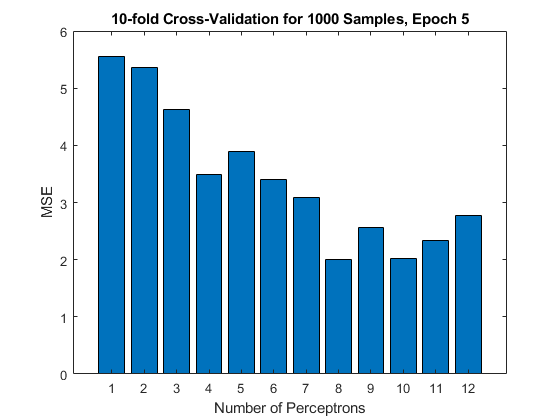

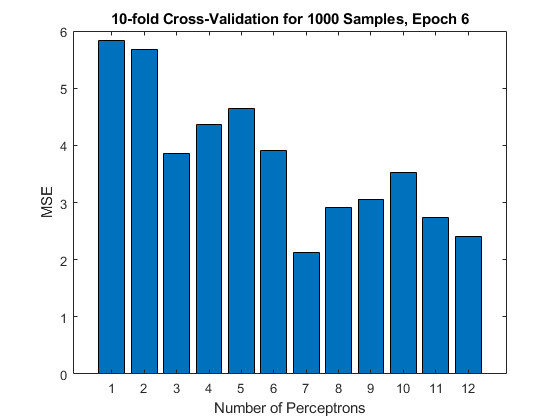

Model Order Selection for 1000 Samples
Number of Perceptrons: 8

[num_perceptrons,init_weights] =  mlp_model_order_selection(d_train);

% Initialize MLP as determined by model order selection
mlp = init_mlp(num_perceptrons,d_train,init_weights);
% Train MLP using full training dataset
mlp = train(mlp,x1_train,x2_train);

% Validate MLP performance on test dataset
y = mlp(x1_test);
% Estimate MSE performance on test data
mse = mean((x2_test-y).^2);
fprintf('Performance (MSE) for 10,000 sample testing dataset: %f',mse);

Performance (MSE) for 10,000 sample testing dataset: 1.379667

# Question 2

For this problem, we trained a Gaussian kernel support vector machine to classify samples generated using generateMultiringDataset.m. Details on the support vector machine implementation for this question can be found in the course document "A Tutorial on Support Vector Machines for Pattern Recognition" by Burges. Model-order selection with cross-validation was used to select an optimal violation contraint hyperparameter $C$ and Gaussian kernel width parameter $\sigma$ that maximized $P(correct) = \frac{\text{Number correct}}{\text{Total samples}}$ for an SVM. The model-order selection procedure is implemented in 'svm_model_order_selection.m', adopted from the script 'svmKfoldCrossValidation.m' provided by Prof. Erdogmuz. The 10-fold cross-validation procedure followed a process similar to the MLP cross-validation used in Question 1. An SVM was trained for each training dataset and validated for each validation fold, while keeping track of performance measures. SVM implementation used the MATLAB function fitcsvm with input parameters 'BoxConstraint' for the parameter $C$ and 'KernelScale' for the parameter $\sigma$, the 'KernelFunction' was specified as 'gaussian' per assignment requirements. When the optimal SVM parameters were selected, a final SVM was trained on the entire 1,000 sample training dataset and validated using the 10,000 sample testing dataset.

### Results

The Gaussian kernel SVM was able to achieve a P(correct) in the range of 0.96 - 0.98 for various iterations of model-order selection and testing. Plots below include training and testing datasets, validation accuracy (P(correct)) on the $C,\sigma$ plane during cross-validation, and predictions/boundaries for the final trained SVM on both datasets. Also included is output of optimal SVM parameters from model-order selection and P(correct) of the final trained SVM on the testing dataset. The optimal hyperparameter $C$ varied across iterations, ranging from 0.02 to 0.8, while the parameter $\sigma$ varied from 10 - 14. 

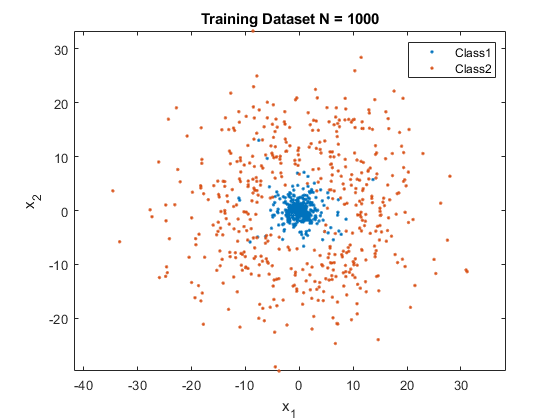

classes = 2;
[d_train,l_train] = generateMultiringDataset(classes,1000);
plot_ring_samples(d_train,l_train,classes,'Training Dataset N = 1000');

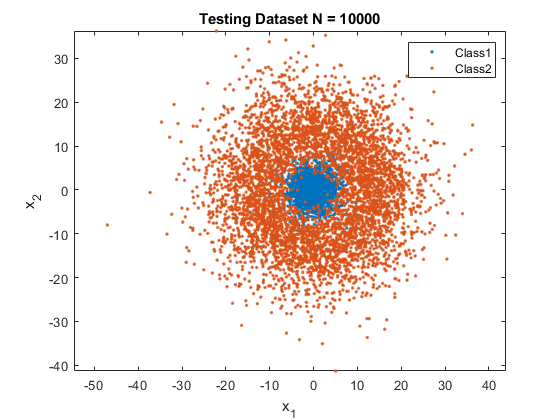

[d_test,l_test] = generateMultiringDataset(classes,10000);
plot_ring_samples(d_test,l_test,classes,'Testing Dataset N = 10000');

Best SVM Parameters for 1000 Samples
C: 0.421697
Sigma: 10.000000

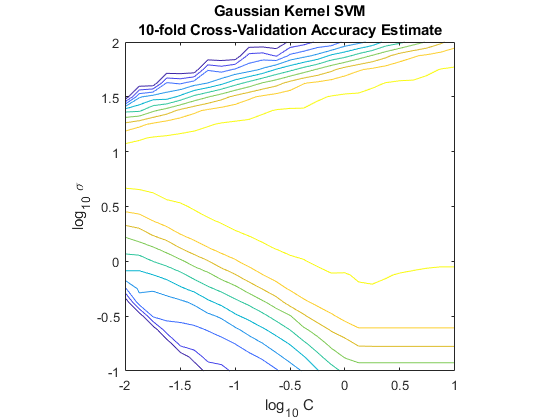

[C, Sigma] = svm_model_order_selection(d_train,l_train);

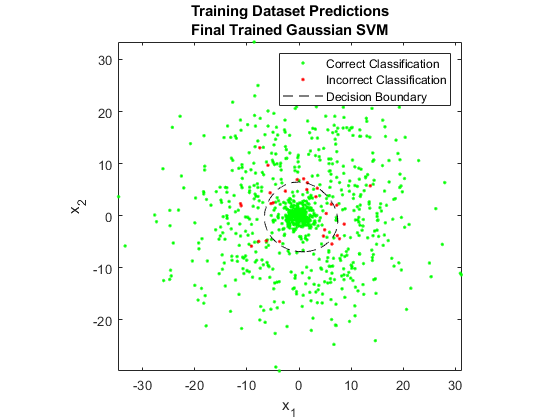

% Train SVM using parameters from model order selection on entire training set
final_SVM = fitcsvm(d_train',l_train,'BoxConstraint',C,'KernelFunction','gaussian','KernelScale',Sigma);

% Evaluate trained SVM on train and test dataset
p_correct_train = plot_errors_svm(d_train,l_train,final_SVM,'Training Dataset');

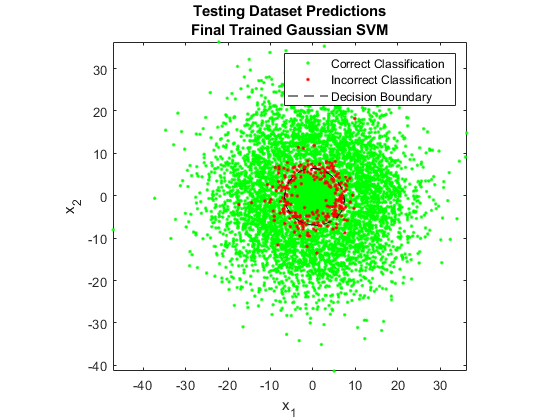

p_correct_test = plot_errors_svm(d_test,l_test,final_SVM,'Testing Dataset');

fprintf('P(correct) for trained SVM on testing dataset: %f',p_correct_test);

P(correct) for trained SVM on testing dataset: 0.973200

# Question 3

For this question, we used GMM clustering to segment two color images. The images were first preprocessed into a 5-dimensional unit hypercube consisting of vectors for each pixel, $v = [\text{row index}, \text{column index},\text{R},\text{G},\text{B}]^T$, where the values in each entry were normalized to [0,1]. Preprocessing was implemented in the script 'image_preprocess.m', adopted from the Summer 2018 Exam 3 solution for Problem 1 provided by Prof. Erdogmuz . The EM algorithm for ML parameter estimation was then used fit GMMs to the resulting hypercube. The MATLAB function 'fitgmdist' implemented the EM-GMM algorithm, and the function 'cluster' provided MAP estimates of clusters for samples using trained GMMs. Maximum number of Expectation-Maximization iterations ('MaxIter' option in fitgmdist) was changed to 100,000 to prevent the fitgmdist algorithm from exiting before convergence was achieved. A regularization weight of $1\times10^{-2}$ was added to each initial covariance matrix estimate for GMM components, to ensure positive-definiteness of the covariance matrices. Final GMM component proportions, covariance matrices, and mean vectors from the highest average log-likelihood GMM from cross-validation was used as the initialization values for the final GMM models of each image. MAP classifcation for samples to clusters was defined as $L_{MAP}=
\underset{\mathbf{n}}{argmax}\ p(L=n|x)$, where $L_{MAP}$ is the cluster associated with a given sample from the MAP decision rule, and $p(L=n|x)$ is the cluster posterior for cluster n. The cluster posterior can be written in the MAP classification as $p(L=n|x) = p(L=n)p(x|L=n)$, where $p(L=n)$ is the cluster prior represented by the n-th cluster mixture weight $\alpha_n$, and $p(x|L=n)$ is the cluster-conditional pdf associated with the n-th GMM component.

We then created segmented images based on cluster labels for each pixel. The optimal number of GMM clusters was selected via 10-fold cross-validation with maximum average log-likelihood on validation samples as the objective.The script 'gmm_model_order.m' implements this cross-validation procedure.

### Results 

Segmented images for M=2 clusters, and for M selected via maximum average validation log-likelihood, are shown below. Also included is a bar plot of average validation log-likelihood values across several numbers of clusters.

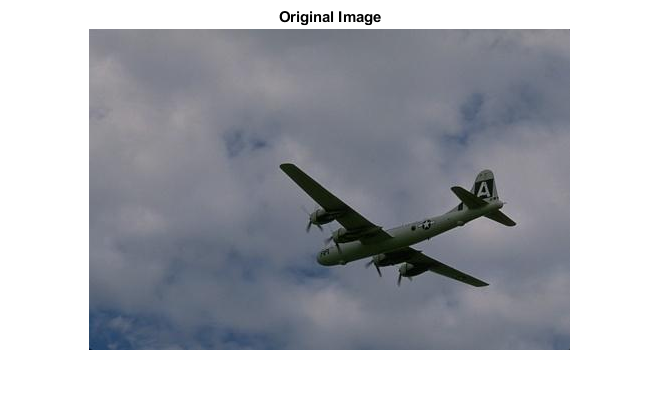

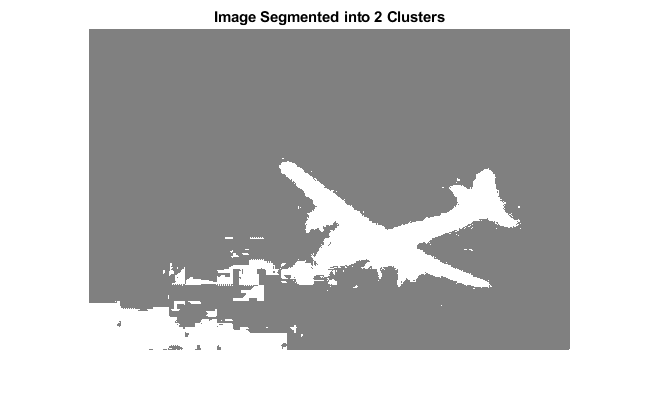

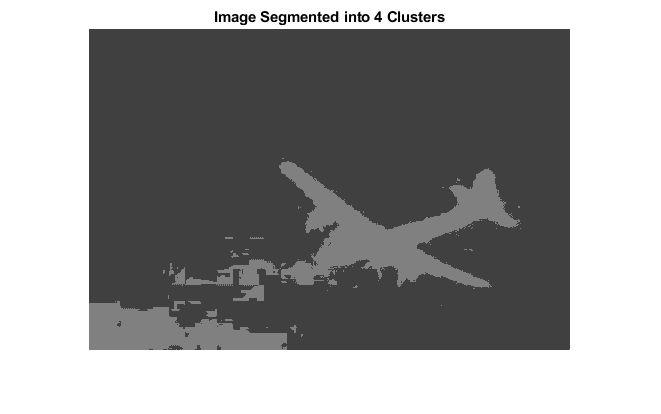

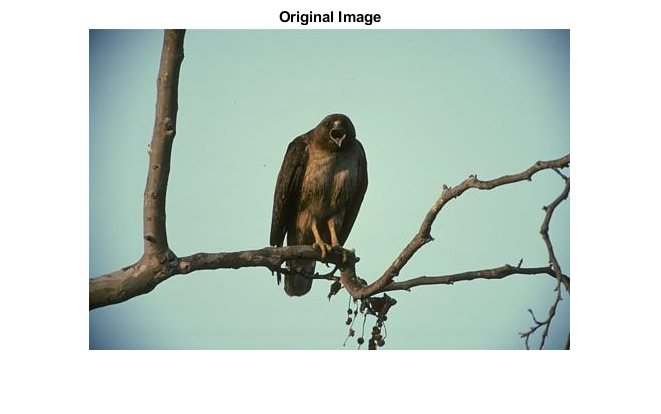

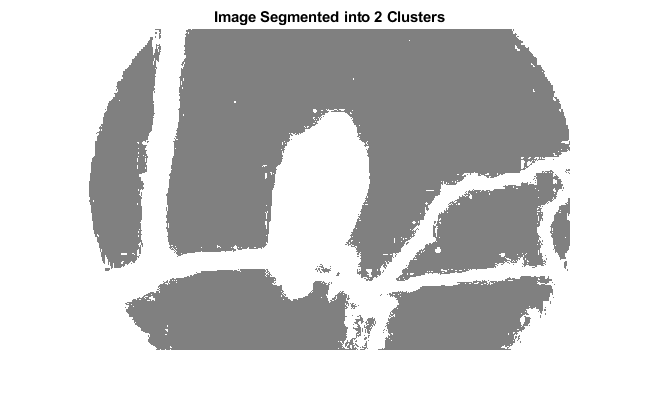

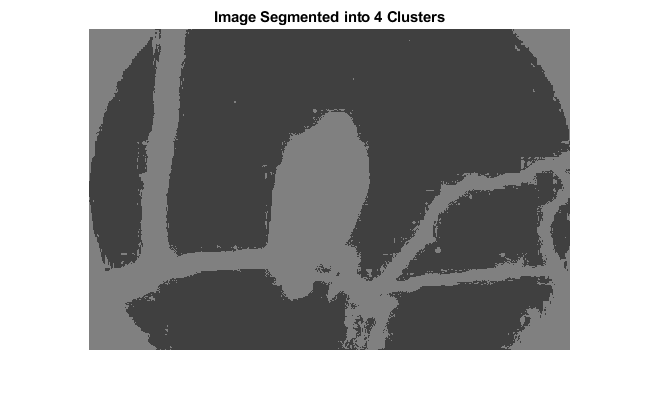

%plane = imread('3096_color.jpg');
bird = imread('42049_color.jpg');
images = {plane,bird};
for ii = 1:length(images)
    [R,C,D] = size(images{ii});
    figure; imshow(images{ii}); title('Original Image');
    % Pre-process image into feature vectors
    features = image_preprocess(images{ii});
    
    % Fit GMM with 2 clusters
    gmm = fitgmdist(features',2);
    labels = cluster(gmm,features');
    labelImage = reshape(labels,R,C);
    figure; imshow(uint8(labelImage*255/2));
    title('Image Segmented into 2 Clusters');
    
    % Model order seletion
    [model_order,init_params] = gmm_model_order(features);
    fprintf('Number of clusters (max. validation log-likelihood): %d',model_order);
    options = statset('MaxIter',100000,'TolFun',1e-4);  
    
    % Fit GMM with model order selected # of clusters
    % Use covariance matrix regularization to ensure positive-definiteness
    S = struct('ComponentProportion',init_params{1},'mu',init_params{2}','Sigma',init_params{3});
    gmm = fitgmdist(features',4,'Options',options,'RegularizationValue',1e-2,'Start',S);
    % MAP classification for clustering
    labels = cluster(gmm,features');
    labelImage = reshape(labels,R,C);
    figure; imshow(uint8(labelImage*255/model_order));
    title(sprintf('Image Segmented into %d Clusters',model_order));
end